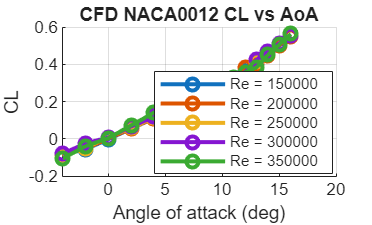

data = readtable('\\wsl.localhost\Ubuntu-22.04\home\mteggeri\OpenFOAM\mteggeri-13\run\naca0012_coefficients_summary.csv');

% Reynolds numbers you specified
Re_vals = [150e3, 200e3, 250e3, 300e3, 350e3];

vels = unique(data.Velocity_m_s);

figure; hold on; grid on;
for i = 1:numel(vels)
    idx = data.Velocity_m_s == vels(i) & strcmp(data.Status,'OK');
    plot(data.AoA_deg(idx), data.CL(idx), '-o', 'DisplayName', sprintf('Re = %.0f', Re_vals(i)),'LineWidth', 2);
end
xlabel('Angle of attack (deg)');
ylabel('CL');
legend('Location','best');
title('CFD NACA0012 CL vs AoA');

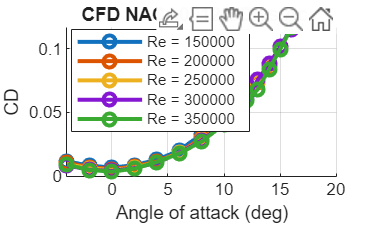


figure; hold on; grid on;
for i = 1:numel(vels)
    idx = data.Velocity_m_s == vels(i) & strcmp(data.Status,'OK');
    plot(data.AoA_deg(idx), data.CD(idx), '-o', 'DisplayName',sprintf('Re = %.0f', Re_vals(i)),'LineWidth', 2);
end
xlabel('Angle of attack (deg)');
ylabel('CD');
legend('Location','best');
title('CFD NACA0012 CD vs AoA');

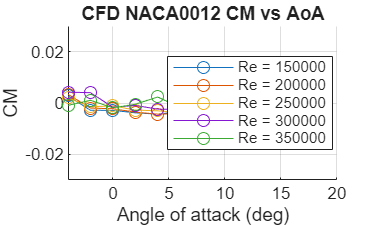


figure; hold on; grid on;
for i = 1:numel(vels)
    idx = data.Velocity_m_s == vels(i) & strcmp(data.Status,'OK');
    plot(data.AoA_deg(idx), data.CM(idx), '-o', 'DisplayName', sprintf('Re = %.0f', Re_vals(i)));
end
xlabel('Angle of attack (deg)');
ylabel('CM');
legend('Location','best');
title('CFD NACA0012 CM vs AoA');
ylim([-30e-3 30e-3])